#  ENME462 Studio 9 Root Locus with MATLAB

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

## 1.1 Motivation for Root Locus Plots

The root locus of a closed-loop system T(s) is the locus of all possible locations of the closed-loop system poles as a specified parameter of the system is varied.

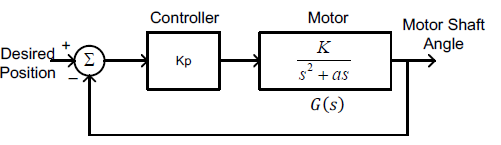

The closed-loop transfer function is 


$$T(s)=\frac{K_pG(s)}{1+K_pG(s)}=\frac{\frac{K_pK}{s(s+a)}}{1+\frac{K_pK}{s(s+a)}}=\frac{K_pK}{s^2+as+K_pK}$$


The poles of the closed-loop system are those values of s which satisfy


$$1+K_pG(s)=0$$


or $s^2+as+K_pK=0$

the closed loop poles 


$$s=-\frac{a}{2}\pm\frac{\sqrt{4K_pK-a^2}}{2}j$$


For a underdamped response with damping ratio $\zeta=\frac{1}{\sqrt2}$, we can set the magnitude of the real and imaginary parts of these roots equal to each other.


$$a=\sqrt{4K_pK-a^2}\quad \rightarrow \quad K_p=
\frac{a^2}{2K}\quad \rightarrow \quad T(s)=\frac{a^2/2}{s^2+as+a^2/2}$$


a = 6.8;
K = 1005;
Kp = a^2/(2*K)

Kp = 0.0230

s = zpk('s');
T = a^2/2 / (s^2 + a*s + a^2/2)


T =
 
         23.12
  --------------------
  (s^2 + 6.8s + 23.12)
 
Continuous-time zero/pole/gain model.



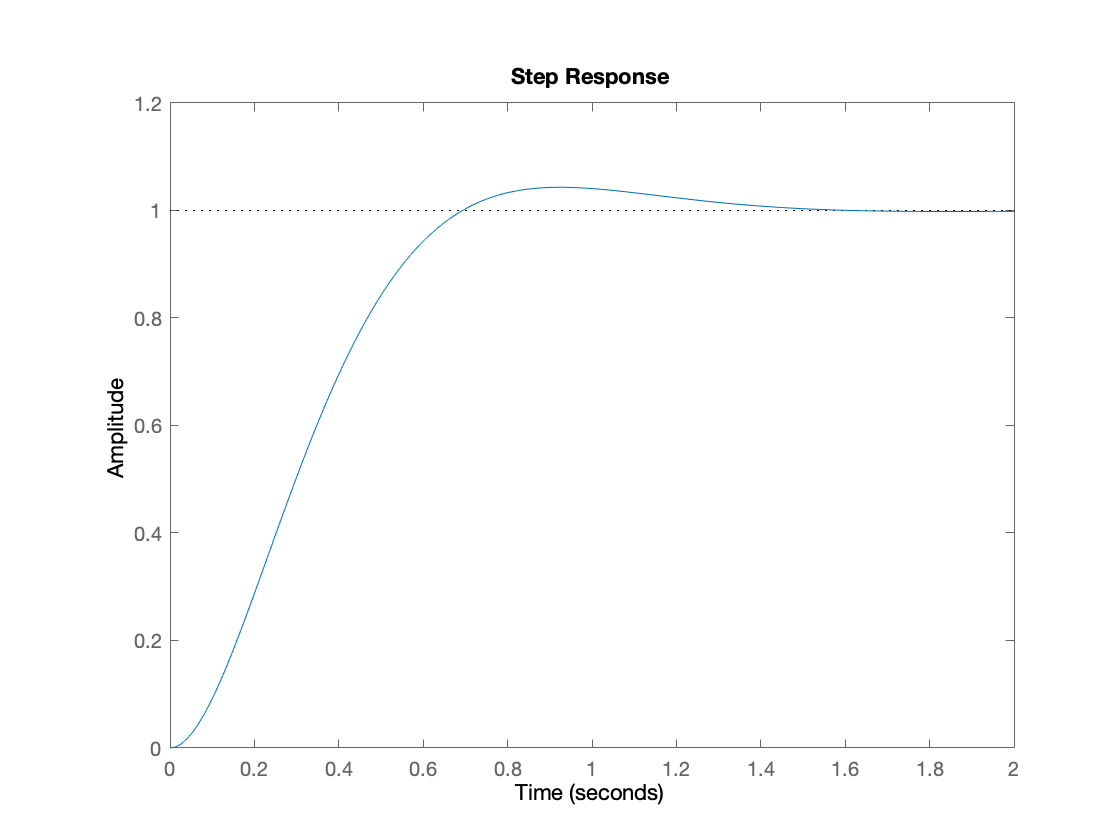

step(T)

## 1.2 Basics of Root Locus Using MATLAB

The root locus of a closed-loop system T(s) is the locus of all possible locations of the closed-loop system poles as a specified parameter of the system is varied.

K = 1005;
a = 6.8;
G = K/(s^2 + a*s)


G =
 
    1005
  ---------
  s (s+6.8)
 
Continuous-time zero/pole/gain model.



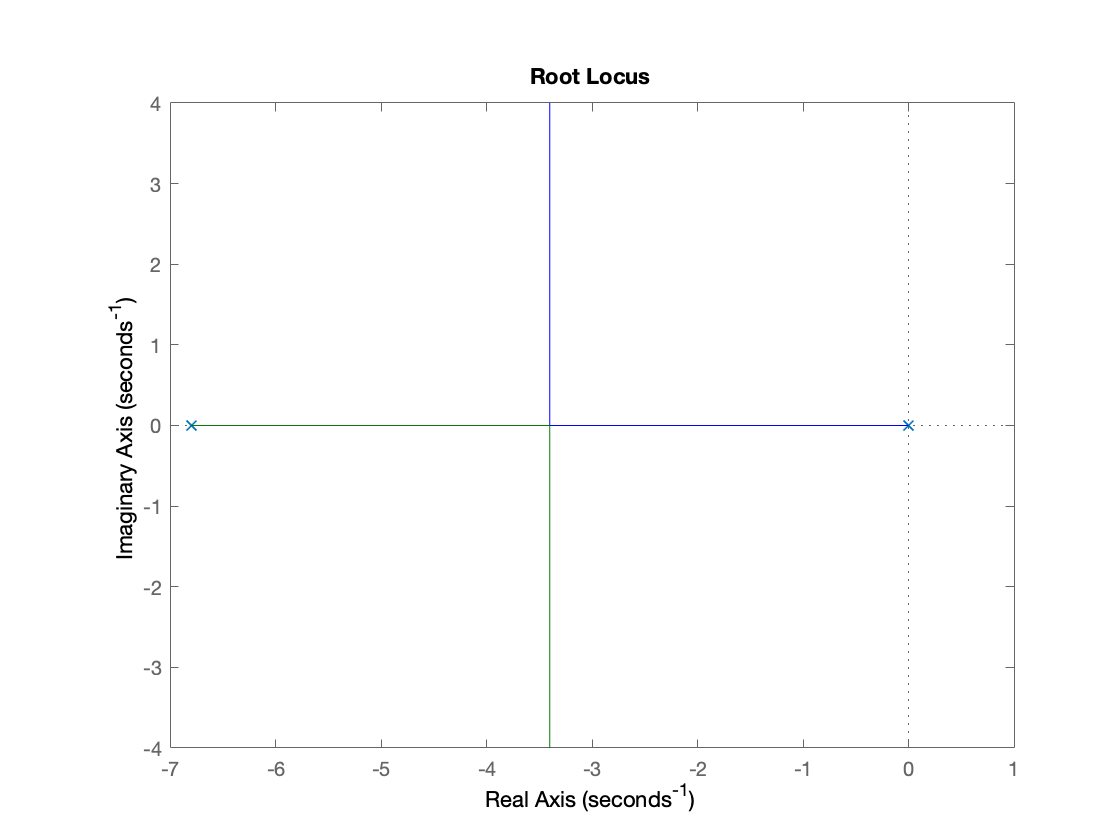

rlocus(G)

Kp = 0.023;
T = feedback(Kp*G,1)


T =
 
         23.115
  --------------------
  (s^2 + 6.8s + 23.12)
 
Continuous-time zero/pole/gain model.



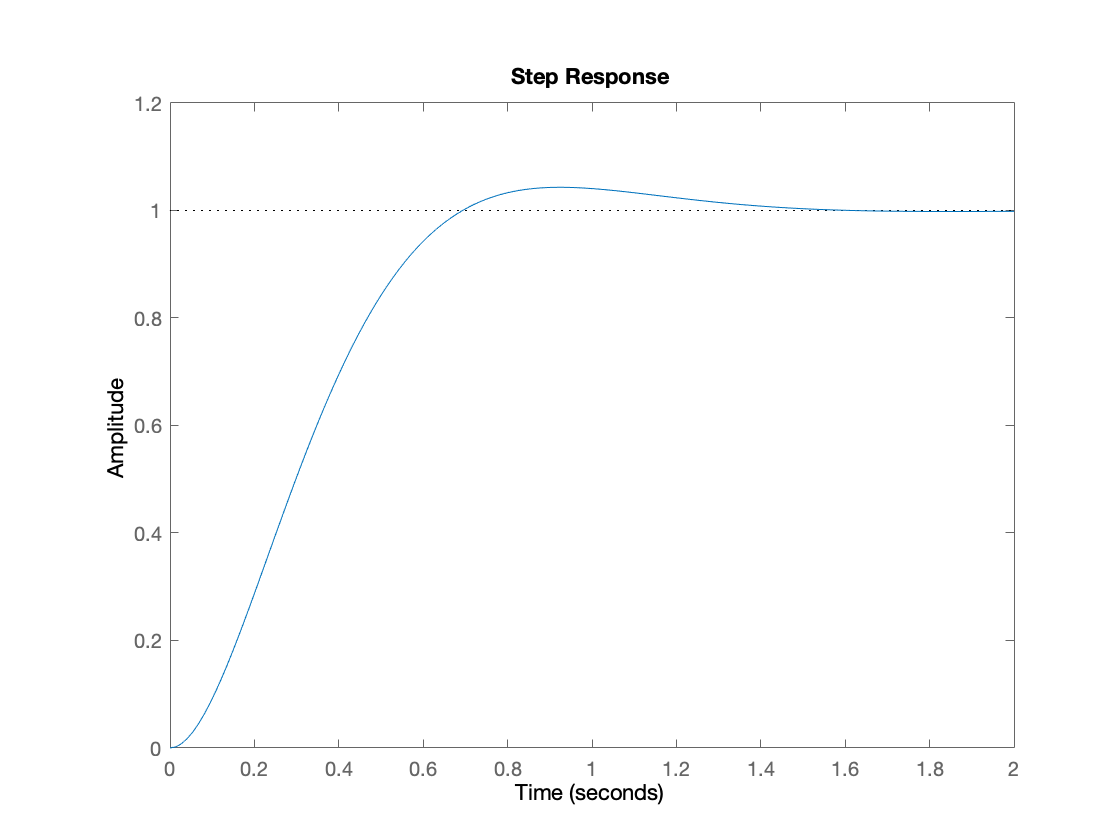

step(T)

stepinfo(T)

ans = struct with fields:
        RiseTime: 0.4470
    SettlingTime: 1.2402
     SettlingMin: 0.9033
     SettlingMax: 1.0432
       Overshoot: 4.3180
      Undershoot: 0
            Peak: 1.0432
        PeakTime: 0.9210


damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.40e+00 + 3.40e+00i     7.07e-01       4.81e+00         2.94e-01    
 -3.40e+00 - 3.40e+00i     7.07e-01       4.81e+00         2.94e-01    


MATLAB command rlocfind takes the system G and a vector of the desired pole locations as arguments and returns the K values.

rlocfind(G,[-3.4+3.4j, -3.4-3.4j])

ans =     0.0230    0.0230


## 1.3 Design Example

Given the following transfer function G(s). Pick a value of $K_p$ that will yield second-order response of the closed-loop function T(s) with a setting time $T_s=4$ sec (assume negative feedback is used).


$$G(s)=\frac{1}{(s+1)(s+3)(s+6)^2}$$


sys = zpk([],[-1,-3,-6,-6],1)


sys =
 
           1
  -------------------
  (s+1) (s+3) (s+6)^2
 
Continuous-time zero/pole/gain model.



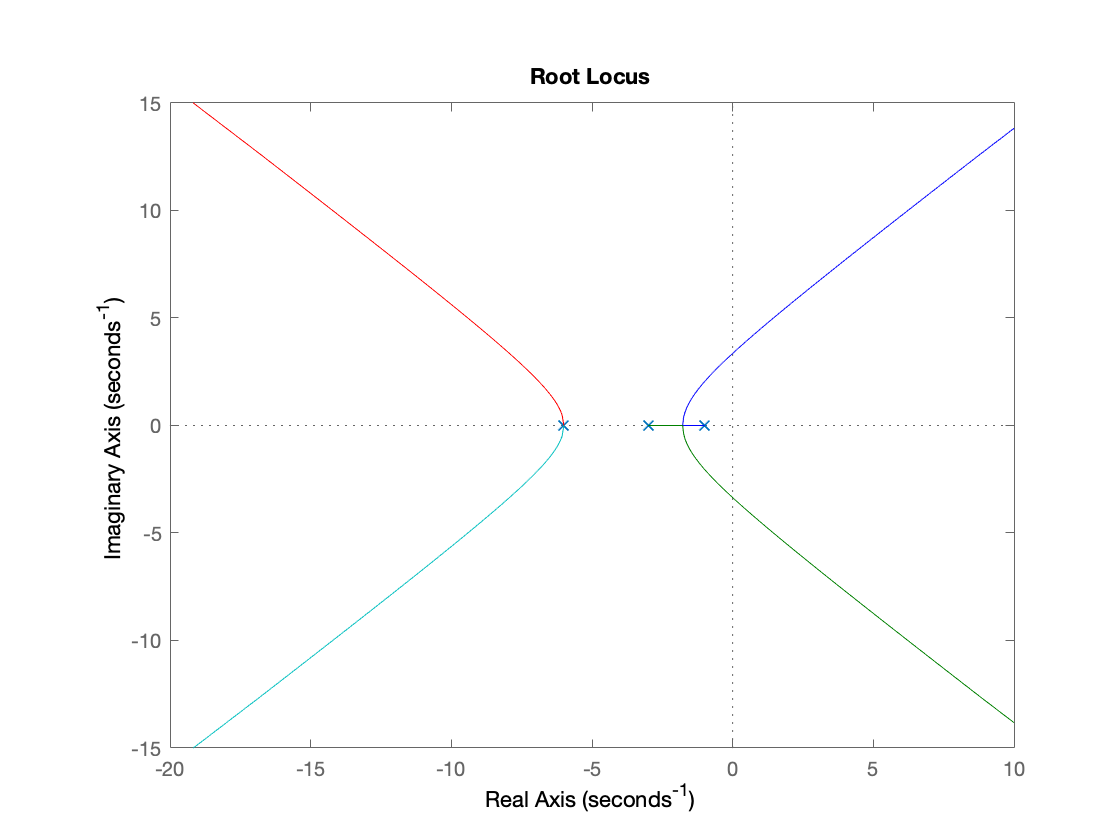

rlocus(sys)

For second-order system $T_s=\frac{4}{\sigma}$ , to achieve $T_s=4$,  the absolute value of the real part of the dominant second-order pole $\sigma=1$.  From the plot tells us that $K_p=163$ will yield the desired $T_s=4$ sec.

G = 163*sys;
T = feedback(G,1)


T =
 
                       163
  ---------------------------------------------
  (s^2 + 2.045s + 5.076) (s^2 + 13.96s + 53.39)
 
Continuous-time zero/pole/gain model.



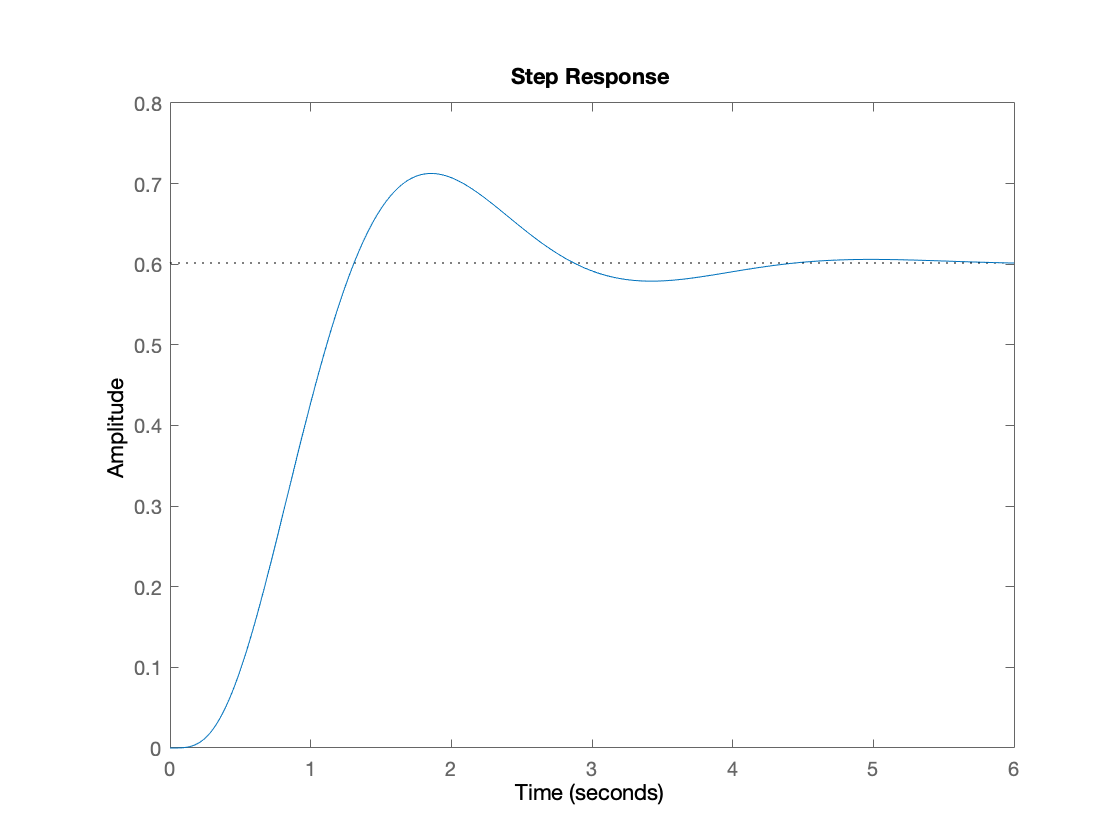

step(T)

stepinfo(T)

ans = struct with fields:
        RiseTime: 0.7659
    SettlingTime: 3.9549
     SettlingMin: 0.5425
     SettlingMax: 0.7126
       Overshoot: 18.4747
      Undershoot: 0
            Peak: 0.7126
        PeakTime: 1.8612


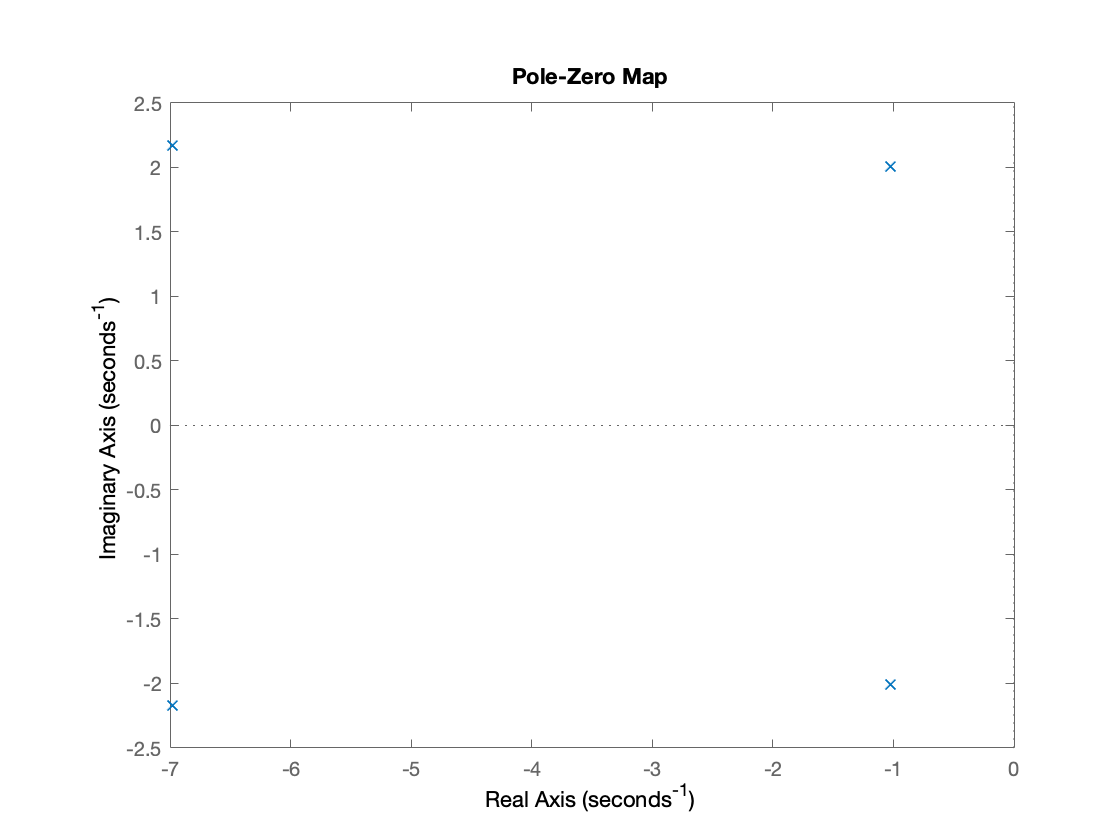

pzmap(T)

## 1.4 Plotting Constant Damping Ratio Lines

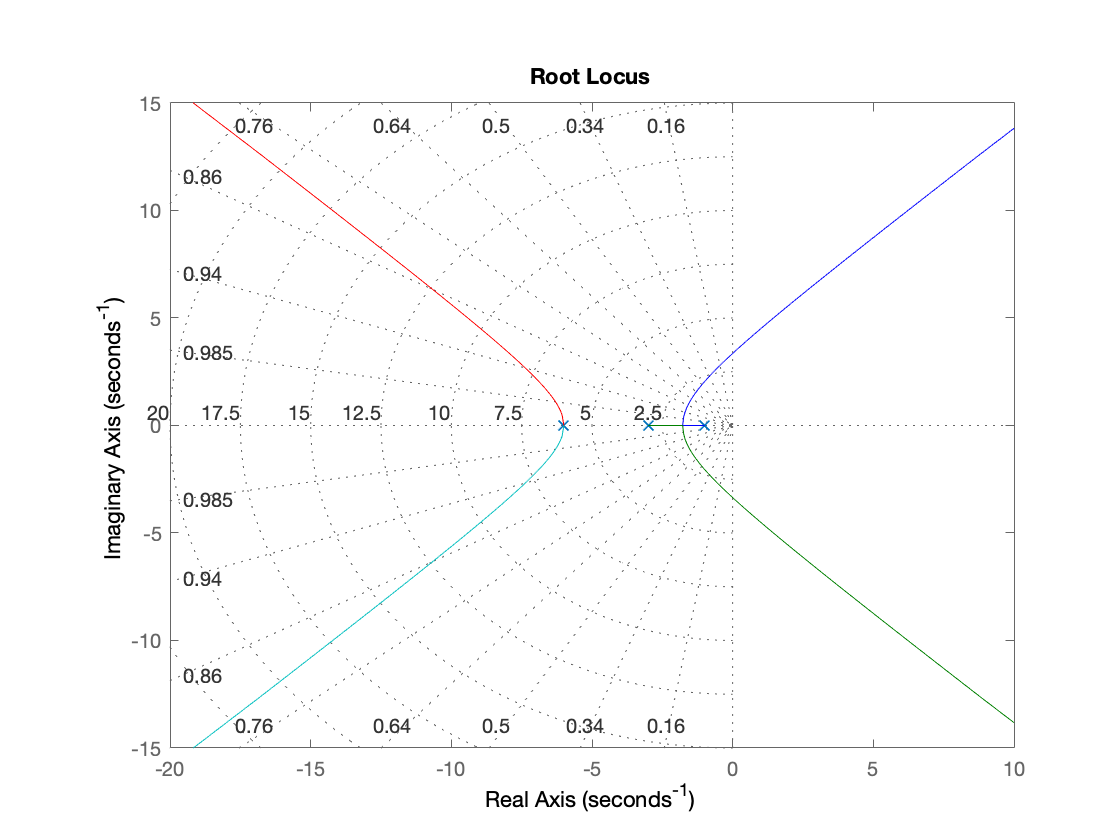

rlocus(G)
sgrid

## 1.5 Design Example Using rtool

MATLAB provides a special interative design tool using the root locus. Let's go through the previous design example(settling time of 4s) using the rltool.

First, define the open-loop transfer function as before:

G = zpk([], [-1, -3, -6, -6],1)


G =
 
           1
  -------------------
  (s+1) (s+3) (s+6)^2
 
Continuous-time zero/pole/gain model.



then, open rltool with G as an argument

rltool(G)